# TG Samuel Afonso

## 1. Inicialização e Busca da Região de Interesse

O processamento da Tomografia de Impedância Elétrica (TIE) inicia-se com o carregamento da matriz 3D contendo os frames do exame em respiração livre (FB). Para guiar a análise, identificamos o pixel com a maior variação temporal (ROI), que representa a região pulmonar com maior fluxo de ar e contraste.

%% Limpeza e inicialização das variáveis
clear all; close all; %clc; 

% Carregar o conjunto de dados de free-breathing
% load('PMI_20\FB_Isol_6\PIG 20 (FB) 125757 127171.mat');
%load('PMI_20\FB_Isol_4\PIG 20 (FB) 76567 77961.mat'); 

%load('PMI_19\FB_Isol_7\PIG 19 (FB) 56712 58067.mat'); % caso bom
load('PMI_20\FB_Isol_1\PIG 20 (FB) 13716 15111.mat'); % melhor NRMSE
load('PMI_22\FB_Isol_3\PIG 22 (FB) 55095 56565.mat'); % ruim NRMSE


%load('PMI_26\FB_Isol_8\PIG 26 (FB) 96270 97860.mat') % caso doente? NRMSE
%dá >2

pletis_ventilacao_3d = data.img_frames;
Fs = 50; % Frequência de amostragem do aparelho de EIT

% Dados de referência (para uso posterior na seção de estatística)
% arquivo_dataset = 'PMI_20\FB_Isol_6\data_fb_125757_127171.mat';
%arquivo_dataset = 'PMI_20\FB_Isol_4\data_fb_76567_77961.mat'; %

%arquivo_dataset = 'PMI_19\FB_Isol_7\data_fb_56712_58067.mat'; % caso bom
arquivo_dataset = 'PMI_20\FB_Isol_1\data_fb_13716_15111.mat'; % melhor NRMSE
arquivo_dataset = 'PMI_22\FB_Isol_3\data_fb_55095_56565.mat'; % ruim NRMSE


%arquivo_dataset = 'PMI_26\FB_Isol_8\data_fb_96270_97860.mat';

%% 1) Pletismograma Global e Identificação do ROI
pletis_ventilacao_1d = squeeze(sum(pletis_ventilacao_3d, [1 2]));
intervalo = 1:length(pletis_ventilacao_1d); 

% 1. Calcula o Mapa TIV (Tidal Impedance Variation) substituindo a variância
z_max = max(pletis_ventilacao_3d, [], 3);
z_min = min(pletis_ventilacao_3d, [], 3);
mapa_tiv = z_max - z_min;

% 2. Define o quadrante Dorsal Direito (conforme Gao et al.)
% Em uma matriz 32x32 padrão, geralmente corresponde à metade inferior (17:32)
% e direita (17:32). Ajuste os índices caso a orientação do seu EIT seja invertida.
mask_dorsal_direito = false(32, 32);
mask_dorsal_direito(17:32, 17:32) = true; 

tiv_mascarado = mapa_tiv;
tiv_mascarado(~mask_dorsal_direito) = 0; % Zera os pixels fora do quadrante

% 3. Encontra as coordenadas do pixel com o maior TIV dentro desse quadrante
[~, idx_max_tiv] = max(tiv_mascarado(:));
[linha_max, coluna_max] = ind2sub(size(tiv_mascarado), idx_max_tiv);

% Criamos um vetor 'stats' fictício apenas para não quebrar a sua função 
% Samuel_visualizar_dados que espera receber a linha e coluna nas posições 2 e 3
stats = [0, linha_max, coluna_max, 0, 0, 0, 0, 0];

% Extrai o sinal isolado do pixel ROI (maior variância positiva)
linha_max = stats(2);
coluna_max = stats(3);
pletis_ROI = squeeze(pletis_ventilacao_3d(linha_max, coluna_max, :));


## 2. Filtragem Prévia e Ancoragem de Linha de Base (Sinal 1D)

A extração da hemodinâmica exige a separação das oscilações da respiração. O bolo de salina produz uma onda lenta de queda de impedância. Para isolá-la, aplica-se um filtro passa-baixa de corte severo (0,17 Hz). Aqui, plota-se as curvas filtradas global e do ROI para identificar o comportamento geral da onda, bem como a distribuição espacial do pixel mais variante.

**Nota Metodológica:** A função `detrend` global gera instabilidade no filtro IIR ao deslocar o início do sinal. Portanto, a linha de base é ancorada na média das 50 primeiras amostras de repouso, garantindo que o filtro inicie em zero e evite artefatos transitórios massivos.

%% 2) Filtragem Prévia (Sinal 1D) para Rastreio do Contraste
% Parâmetros de Filtragem
f_v = 0.50;    % Corte para preservar a respiração suína
f_p = 0.17;    % Corte agressivo para preservar a onda da salina

% Ancora o início do sinal do ROI no zero (média das 50 primeiras amostras)
linha_base_ROI = mean(pletis_ROI(1:50));
pletis_ROI_zero = pletis_ROI - linha_base_ROI;

% Aplica o filtro passa-baixa no sinal do ROI para extrair a onda de perfusão
[pletis_ROI_perf, ~] = passa_baixa_sos(pletis_ROI_zero, f_p, Fs);

% Filtra também o pletismograma global apenas para fins de visualização final
linha_base_global = mean(pletis_ventilacao_1d(1:50));
pletis_global_zero = pletis_ventilacao_1d - linha_base_global;
[pletis_perf, ~] = passa_baixa_sos(pletis_global_zero, f_p, Fs);

%% 3) Determinação Automática do Intervalo de Perfusão (Salina)
% A margem de 100 amostras ignora o transiente inicial inevitável do filtro IIR
margem_seguranca = 100; 

% 1. Encontra o ponto de mínimo absoluto NO SINAL FILTRADO DO ROI (mesma
% abordagem de Gao, Figura 1.C)
[~, idx_fim_relativo] = min(pletis_ROI_perf(margem_seguranca:end));
idx_fim = idx_fim_relativo + margem_seguranca - 1; 

% 2. Estima a linha de base EELI usando o sinal filtrado do ROI
janela_estavel = 200:round(idx_fim / 1.5); 
linha_EELI = mean(pletis_ROI_perf(janela_estavel));

% 3. Busca regressiva NO SINAL FILTRADO DO ROI para encontrar o cruzamento EELI
idx_inicio = idx_fim;
while idx_inicio > margem_seguranca && pletis_ROI_perf(idx_inicio) < linha_EELI
    idx_inicio = idx_inicio - 1;
end

fprintf('Intervalo detectado pelo ROI: Início em x = %d | Mínimo absoluto em x = %d\n', idx_inicio, idx_fim);

Intervalo detectado pelo ROI: Início em x = 779 | Mínimo absoluto em x = 898


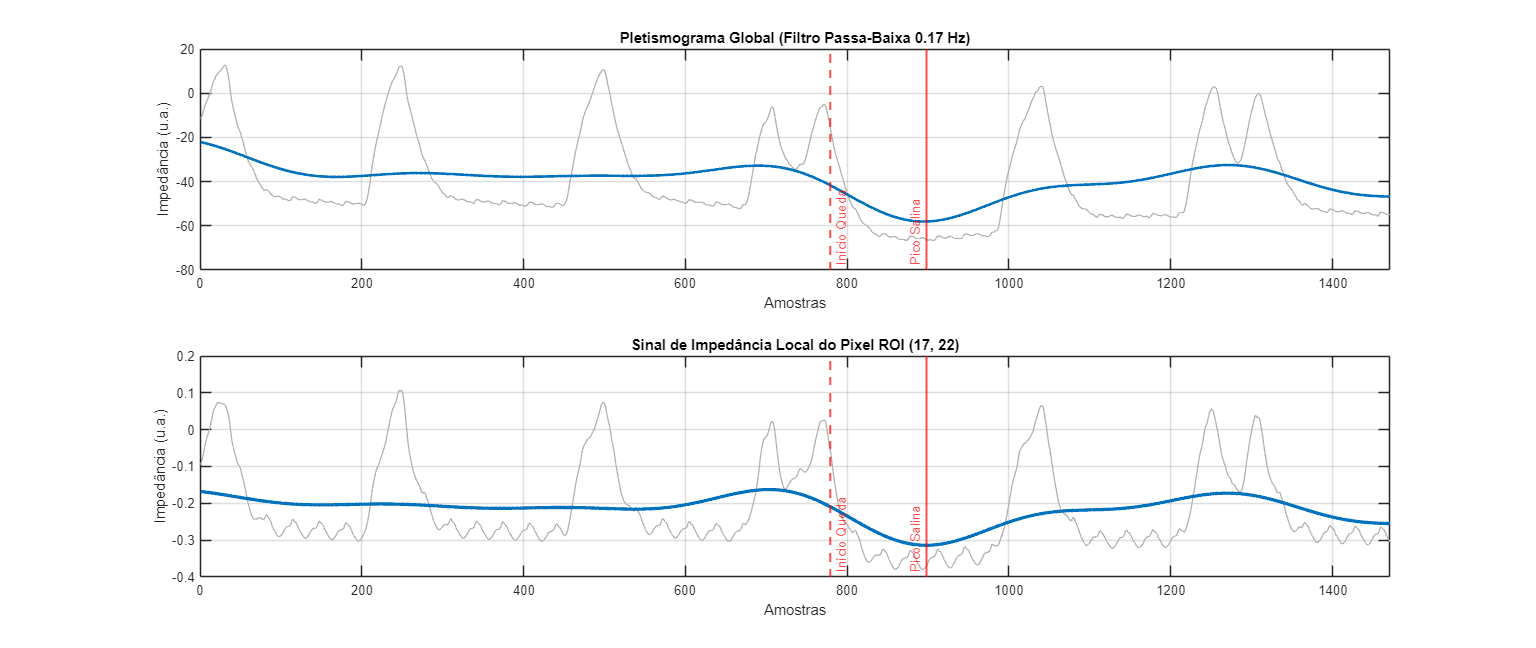


%% 4) Visualização Inicial dos Sinais e Marcações
visualizar_minROI = false;  % opção de visualizar o ROI de mínima variação de impedância

% IMPORTANTE: A função Samuel_visualizar_dados precisa estar preparada para 
% receber idx_inicio e idx_fim se você desejar que ela plote as linhas verticais.

% Passa agora os sinais filtrados para a função de visualização poder plotá-los
[pletis_global, pletis_ROI_out] = Samuel_visualizar_dados_Gao(pletis_ventilacao_3d, pletis_global_zero, pletis_perf, pletis_ROI_zero, pletis_ROI_perf, stats, intervalo, visualizar_minROI, idx_inicio, idx_fim);

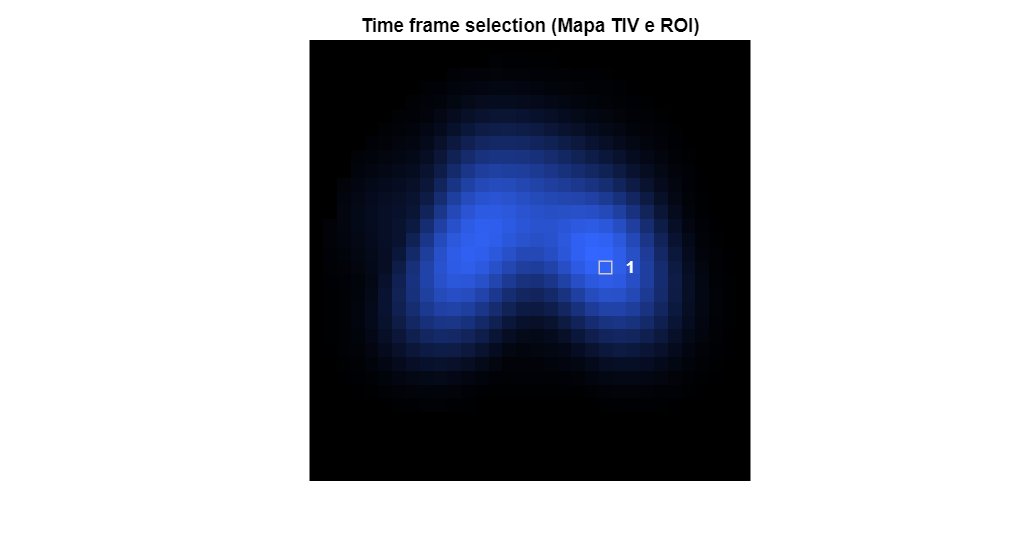


%% 4.1) Visualização Espacial do Pixel ROI (Análogo à Fig 1.A de Gao)
figure('Units', 'normalized', 'Position', [0.3 0.3 0.4 0.5], 'Name', 'Seleção do Pixel de Interesse (ROI)');

% Utiliza o mapa_tiv (Variação de Impedância) calculado na Seção 1
imagesc(mapa_tiv);

% --- Criação de um Colormap Preto e Azul (Idêntico ao de Gao) ---
cor_fundo = [0 0 0];
cor_pulmao = [0.2 0.4 1];
cmap_azul = zeros(256, 3);
cmap_azul(:,1) = linspace(cor_fundo(1), cor_pulmao(1), 256)';
cmap_azul(:,2) = linspace(cor_fundo(2), cor_pulmao(2), 256)';
cmap_azul(:,3) = linspace(cor_fundo(3), cor_pulmao(3), 256)';
colormap(gca, cmap_azul);

% Remove os eixos para o visual "limpo" de imagem médica
axis square off;
hold on;

% Demarca o pixel ROI (de maior TIV) com um quadrado branco
plot(coluna_max, linha_max, 's', 'MarkerEdgeColor', [0.8 0.8 0.8], 'MarkerSize', 12, 'LineWidth', 1.5);

% Adiciona o rótulo "1" ao lado do quadrado, como na imagem de Gao
text(coluna_max + 1.5, linha_max, '1', 'Color', 'white', 'FontSize', 12, 'FontWeight', 'bold');

title('Time frame selection (Mapa TIV e ROI)', 'Color', 'black', 'FontSize', 14);
hold off;

## 3. Análise Espectral e Mapeamento 2D da Perfusão

Com a janela temporal do contraste definida no sinal 1D, o algoritmo varre os 1024 pixels da imagem, aplica o mesmo tratamento de ancoragem e extrai a variação regional de perfusão para montar o mapa espacial 2D. Além disso, exibe-se o espectro em frequência do pletismograma e, depois, plota-se o gradiente de variação temporal de impedância em cada pixel ao longo de 8 momentos diferentes, permitindo visualizar o "wash-in" da solução salina.

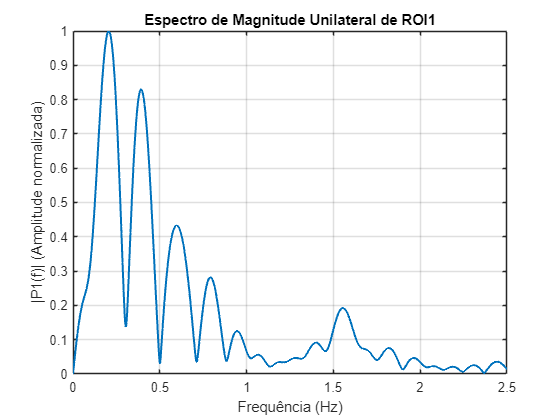

%% Análise Espectral (Sinal limpo de DC)
if length(janela_estavel) >= 9
    pletis_ROI_fft = detrend(pletis_ROI(janela_estavel), 'constant');
else
    pletis_ROI_fft = detrend(pletis_ROI(1:min(length(pletis_ROI), 500)), 'constant');
end
[P1, vetor_f] = FFT_Samuel(pletis_ROI_fft);


%% Filtragem Espacial Pixel a Pixel (Matriz 3D)
fprintf('Iniciando filtragem espacial 3D...\n');

Iniciando filtragem espacial 3D...


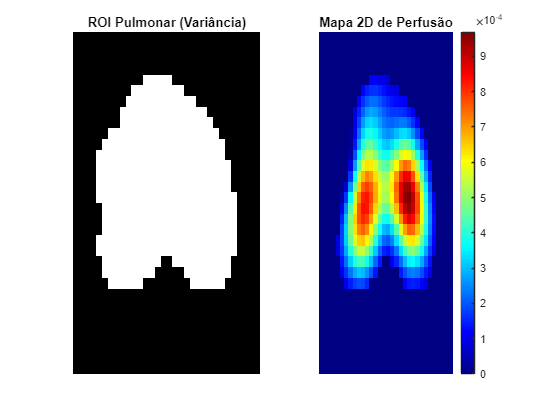

[matriz_perf_3d, matriz_vent_3d, mascara_pulmao] = filt_Matriz3D(pletis_ventilacao_3d, Fs, f_p, f_v);

%% Extração do Mapa de Perfusão 2D
%[linhas, colunas, ~] = size(matriz_perf_3d);
%%mapa_perfusao_2d = zeros(linhas, colunas);
%for i = 1:linhas
%    for j = 1:colunas
%        if mascara_pulmao(i, j)
%            sinal_janela = squeeze(matriz_perf_3d(i, j, idx_inicio:idx_fim));
%            queda_amplitude = sinal_janela(1) - min(sinal_janela);
%            if queda_amplitude > 0
%                mapa_perfusao_2d(i, j) = queda_amplitude;
%            end
%        end
%    end
%end

%% Extração do Mapa de Perfusão 2D
[linhas, colunas, ~] = size(matriz_perf_3d);
mapa_perfusao_2d = zeros(linhas, colunas);

% Vetor de tempo (eixo x) correspondente ao tamanho da janela
t_janela = (1:(idx_fim - idx_inicio + 1))'; 

for i = 1:linhas
    for j = 1:colunas
        if mascara_pulmao(i, j)
            % Extrai a curva regional do pixel
            sinal_janela = squeeze(matriz_perf_3d(i, j, idx_inicio:idx_fim));
            
            % Garante que a dimensão do sinal seja coluna
            sinal_janela = sinal_janela(:);
            
            % Ajuste linear de 1ª ordem (pixel-wise linear fitting de Gao)
            % P = polyfit(X, Y, N) retorna os coeficientes [slope, intercept]
            coeficientes = polyfit(t_janela, sinal_janela, 1);
            
            % O fluxo da solução salina causa uma QUEDA de impedância (slope negativo).
            % O valor de perfusão será a magnitude dessa queda (o módulo da inclinação).
            slope_perfusao = -coeficientes(1); 
            
            % Retém apenas taxas de descida válidas
            if slope_perfusao > 0
                mapa_perfusao_2d(i, j) = slope_perfusao;
            end
        end
    end
end



%% Visualização do Mapa Final e da Máscara
figure;
subplot(1,2,1); imagesc(mascara_pulmao);
title('ROI Pulmonar (Variância)'); colormap(gca, gray); axis off;
subplot(1,2,2); imagesc(mapa_perfusao_2d);
colorbar; title('Mapa 2D de Perfusão');
colormap(gca, jet); axis off;


%% Visualização da Dinâmica Espaço-Temporal do Contraste (8 Frames)
% Foca estritamente na janela de "wash-in" (da quebra da EELI até o fundo do poço)
idx_fim_visualizacao = idx_fim;

if idx_fim_visualizacao > 1356
    idx_fim_visualizacao = 1356;
end

fprintf('Gerando frames de perfusão na janela [%d : %d]...\n', idx_inicio, idx_fim_visualizacao);

Gerando frames de perfusão na janela [779 : 898]...


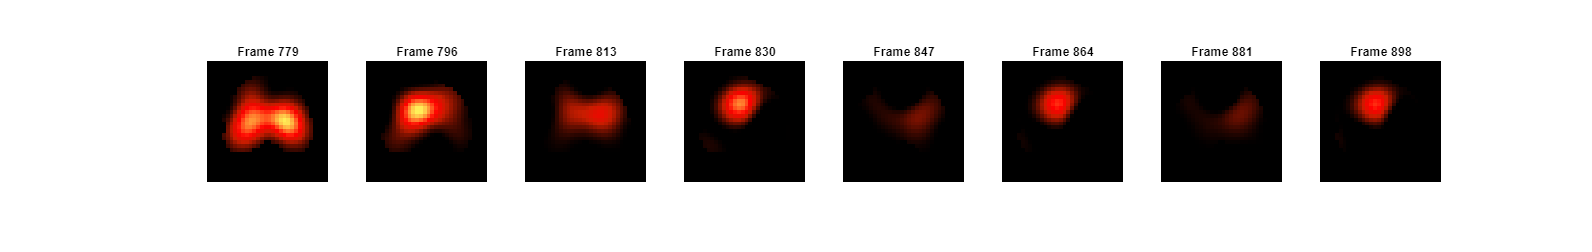

frames_referencia = plot_frames_Samuel(pletis_ventilacao_3d, mascara_pulmao, idx_inicio, idx_fim_visualizacao); % derivada do sinal de impedância bruto

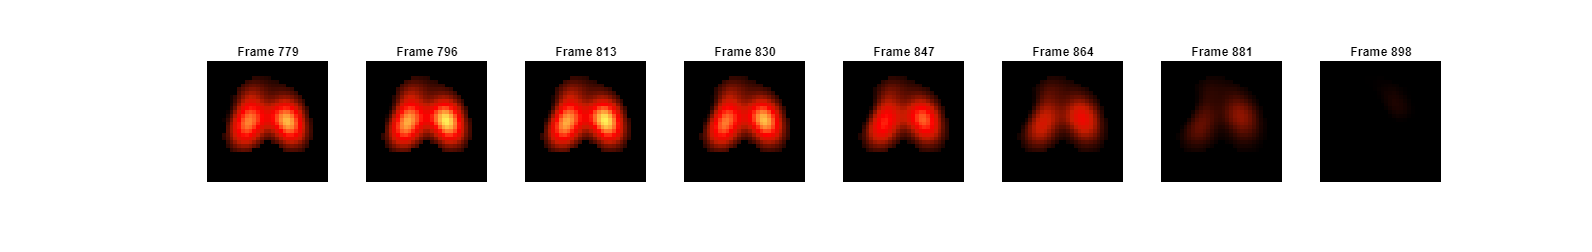

frames_marcados = plot_frames_Samuel(matriz_perf_3d, mascara_pulmao, idx_inicio, idx_fim_visualizacao); % derivada do sinal de perfusão filtrado

## 4. Grupo de Controle: Avaliação da Perfusão Pulsátil

Como alternativa ao contraste, testa-se a extração da perfusão pulsátil card́ıaca via filtro passa-banda (1,0 - 1,66 Hz). Devido à sobreposição dos harmônicos respiratórios no espectro pulmonar, observa-se uma modulação rítmica indesejada vazando para o sinal card́ıaco, evidenciando as limitações da filtragem clássica em frequência. Como isso não deu certo, retirei dos resultados.

%% Validação de Perfusão Pulsátil (Filtro Passa-Banda Cardíaco - Grant et al.)
%f_c_min = 1.0;  % Limite inferior cardíaco suíno (60 bpm)
%f_c_max = 1.67; % Limite superior cardíaco suíno (100 bpm)
% Projeto do filtro passa-banda de 5ª ordem (SOS para estabilidade numérica)
%Wn_bp = [f_c_min, f_c_max] / (Fs / 2);
%[z_bp, p_bp, k_bp] = butter(5, Wn_bp, 'bandpass');
%[sos_bp, g_bp] = zp2sos(z_bp, p_bp, k_bp);

%pletis_cardiaco = filtfilt(sos_bp, g_bp, pletis_global_zero);

%figure;
%plot(pletis_cardiaco, 'Color', [0.8 0.2 0.2], 'LineWidth', 1.5);
%title('Perfusão Pulsátil: Componente Cardíaca Isolada (1.0 - 1.66 Hz)');
%xlabel('Amostras'); ylabel('Impedância (u.a.)'); grid on;
%xlim([0 500]);

## 5. Validação Estatística contra o Modelo do Dataset

Para aferir a eficácia do filtro Butterworth, comparam-se os resultados com os mapas obtidos por modelos matemáticos preditivos do dataset (que removem ativamente a ventilação baseada no fluxo). Analisam-se a correlação de Spearman e a concordância de Bland-Altman para a distribuição de perfusão. Seguindo a abordagem de Gao, também calcula-se o Teste de Wilcoxon. Uma comparação da distribuição regional em quadrantes foi realizada para referência.

%% Validação Estatística: Nosso Filtro vs. Modelo do Dataset
dados_ref = load(arquivo_dataset);
pletis_ref_3d = dados_ref.data_fb.img_frames; 

mapa_ref_2d = zeros(linhas, colunas);

% Usa o mesmo vetor de tempo do nosso filtro
t_janela = (1:(idx_fim - idx_inicio + 1))'; 

for i = 1:linhas
    for j = 1:colunas
        if mascara_pulmao(i, j)
            sinal_janela_ref = squeeze(pletis_ref_3d(i, j, idx_inicio:idx_fim));
            
            % Garante que a dimensão seja coluna
            sinal_janela_ref = sinal_janela_ref(:);
            
            % Aplica exatamente a mesma métrica (slope/inclinação) de Xu/Gao na referência
            coef_ref = polyfit(t_janela, sinal_janela_ref, 1);
            slope_ref = -coef_ref(1);
            
            if slope_ref > 0
                mapa_ref_2d(i, j) = slope_ref;
            end
        end
    end
end

% 1. Normalização (Porcentagem de Distribuição Regional %)
mapa_nosso_norm = (mapa_perfusao_2d / sum(mapa_perfusao_2d(:))) * 100;
mapa_ref_norm = (mapa_ref_2d / sum(mapa_ref_2d(:))) * 100;
pixels_nosso = mapa_nosso_norm(mascara_pulmao);
pixels_ref = mapa_ref_norm(mascara_pulmao);

%% 2. Cálculos Estatísticos
r_spearman = corr(pixels_ref, pixels_nosso, 'Type', 'Spearman');

% Teste não-paramétrico de Wilcoxon (Gao et al.)
[p_wilcoxon, h] = signrank(pixels_ref, pixels_nosso);
fprintf('Correlação de Spearman (r): %.3f\n', r_spearman);

Correlação de Spearman (r): 0.107


fprintf('Teste de Wilcoxon (p-valor): %.4f\n', p_wilcoxon); % p > 0.05 indica equivalência

Teste de Wilcoxon (p-valor): 0.0272


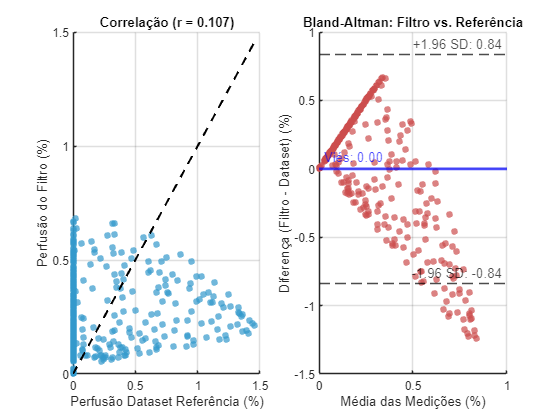


medias = (pixels_ref + pixels_nosso) / 2;
diferencas = pixels_nosso - pixels_ref;
vies = mean(diferencas);
desvio_padrao = std(diferencas);
limite_sup = vies + 1.96 * desvio_padrao;
limite_inf = vies - 1.96 * desvio_padrao;

figure;
subplot(1,2,1);
scatter(pixels_ref, pixels_nosso, 25, 'filled', 'MarkerFaceColor', [0.2 0.6 0.8], 'MarkerFaceAlpha', 0.7);
hold on;
plot([0 max(pixels_ref)], [0 max(pixels_ref)], '--k', 'LineWidth', 1.5);
title(['Correlação (r = ' num2str(r_spearman, '%.3f') ')']);
xlabel('Perfusão Dataset Referência (%)'); ylabel('Perfusão do Filtro (%)'); grid on;

subplot(1,2,2);
scatter(medias, diferencas, 25, 'filled', 'MarkerFaceColor', [0.8 0.3 0.3], 'MarkerFaceAlpha', 0.7);
hold on;
yline(vies, '-b', ['Viés: ' num2str(vies, '%.2f')], 'LineWidth', 2, 'LabelHorizontalAlignment', 'left');
yline(limite_sup, '--k', ['+1.96 SD: ' num2str(limite_sup, '%.2f')]);
yline(limite_inf, '--k', ['-1.96 SD: ' num2str(limite_inf, '%.2f')]);
title('Bland-Altman: Filtro vs. Referência');
xlabel('Média das Medições (%)'); ylabel('Diferença (Filtro - Dataset) (%)'); grid on;


%% 3. Extração dos 4 Quadrantes Regionais
RV_nosso = sum(sum(mapa_nosso_norm(1:16, 1:16) .* mascara_pulmao(1:16, 1:16)));
LV_nosso = sum(sum(mapa_nosso_norm(1:16, 17:32) .* mascara_pulmao(1:16, 17:32)));
RD_nosso = sum(sum(mapa_nosso_norm(17:32, 1:16) .* mascara_pulmao(17:32, 1:16)));
LD_nosso = sum(sum(mapa_nosso_norm(17:32, 17:32) .* mascara_pulmao(17:32, 17:32)));

RV_ref = sum(sum(mapa_ref_norm(1:16, 1:16) .* mascara_pulmao(1:16, 1:16)));
LV_ref = sum(sum(mapa_ref_norm(1:16, 17:32) .* mascara_pulmao(1:16, 17:32)));
RD_ref = sum(sum(mapa_ref_norm(17:32, 1:16) .* mascara_pulmao(17:32, 1:16)));
LD_ref = sum(sum(mapa_ref_norm(17:32, 17:32) .* mascara_pulmao(17:32, 17:32)));

fprintf('\n==== COMPARAÇÃO REGIONAL (4 QUADRANTES) ====\n');


==== COMPARAÇÃO REGIONAL (4 QUADRANTES) ====


fprintf('Região           | Modelo Dataset |  Nosso Filtro  | Diferença Absoluta\n');

Região           | Modelo Dataset |  Nosso Filtro  | Diferença Absoluta


fprintf('Ventral Direito  |     %5.2f%%    |     %5.2f%%    |      %5.2f%%\n', RV_ref, RV_nosso, abs(RV_ref - RV_nosso));

Ventral Direito  |     44.20%    |     24.98%    |      19.21%


fprintf('Ventral Esquerdo |     %5.2f%%    |     %5.2f%%    |      %5.2f%%\n', LV_ref, LV_nosso, abs(LV_ref - LV_nosso));

Ventral Esquerdo |     55.80%    |     28.77%    |      27.03%


fprintf('Dorsal Direito   |     %5.2f%%    |     %5.2f%%    |      %5.2f%%\n', RD_ref, RD_nosso, abs(RD_ref - RD_nosso));

Dorsal Direito   |      0.00%    |     23.09%    |      23.09%


fprintf('Dorsal Esquerdo  |     %5.2f%%    |     %5.2f%%    |      %5.2f%%\n', LD_ref, LD_nosso, abs(LD_ref - LD_nosso));

Dorsal Esquerdo  |      0.00%    |     23.15%    |      23.15%


## 6. Comparação de curvas: Original vs filtrada vs referência

Uma primeira confirmação visual da similaridade entre o sinal filtrado e o sinal que se pretende atingir - o sinal pré-filtrado por outro método, realizado por Ágape - é plotar ambas as curvas simultaneamente, juntamente com o pletismograma bruto como comparativo. Os frames cuja perfusão foi destacada em imagens acima também foram destacados no gráfico.

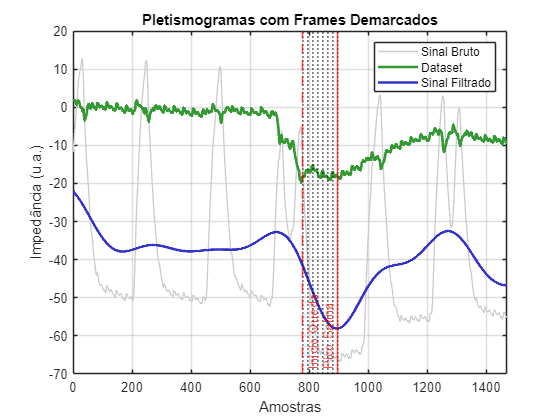

%% Validação Visual (1D): Nosso Filtro vs. Modelo do Dataset com Marcação dos Frames

pletis_ref_global = squeeze(sum(pletis_ref_3d, [1 2]));
linha_base_ref = mean(pletis_ref_global(1:50));
pletis_ref_zero = pletis_ref_global - linha_base_ref;

figure;
plot(pletis_global_zero, 'Color', [0.8 0.8 0.8], 'LineWidth', 1); hold on;
plot(pletis_ref_zero, 'Color', [0.2 0.6 0.2], 'LineWidth', 2); 
plot(pletis_perf, 'Color', [0.2 0.2 0.8], 'LineWidth', 2); 

% Adiciona as linhas verticais correspondentes aos 6 frames plotados
for i = 1:length(frames_marcados)
    xline(frames_marcados(i), 'k:', 'LineWidth', 1); 
end
xline(idx_inicio, 'r--', 'Início Queda', 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'right');
xline(idx_fim, 'r-', 'Pico Salina', 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'left');

title('Pletismogramas com Frames Demarcados');
xlabel('Amostras'); ylabel('Impedância (u.a.)');
legend('Sinal Bruto', 'Dataset', 'Sinal Filtrado', 'Location', 'northeast');grid on; xlim([0 length(pletis_perf)]);

## 7. Mapeamento da Relação Ventilação/Perfusão (V/Q)

Incorporou-se um gráfico de correlação V/Q tal qual no estudo de Xu et al (2025), também como referência. Esse dado não precisa ir ao trabalho final, por enquanto está mais como curiosidade.

%% 8. Mapeamento da Relação Ventilação/Perfusão (V/Q)
% 1. Extração do Mapa 2D de Ventilação a partir do sinal filtrado (0.50 Hz)
[linhas, colunas, ~] = size(matriz_vent_3d);
mapa_vent_2d = zeros(linhas, colunas);

for i = 1:linhas
    for j = 1:colunas
        if mascara_pulmao(i, j)
            % Isola o sinal de ventilação do pixel
            sinal_vent_pixel = squeeze(matriz_vent_3d(i, j, :));
            
            % Calcula a amplitude da ventilação (TIV) no pixel
            amplitude_vent = max(sinal_vent_pixel) - min(sinal_vent_pixel);
            
            if amplitude_vent > 0
                mapa_vent_2d(i, j) = amplitude_vent;
            end
        end
    end
end

%% 8. Mapeamento da Relação Ventilação/Perfusão (V/Q) - Método Xu et al. (Gao)
% As matrizes mapa_vent_2d e mapa_perfusao_2d já foram extraídas nos passos anteriores.

% 1. Limiarização (Threshold de 20% do Máximo Global)
limiar_V = 0.20 * max(mapa_vent_2d(:));
limiar_Q = 0.20 * max(mapa_perfusao_2d(:));

% Criação de máscaras lógicas para pixels ativos
mask_V = mapa_vent_2d > limiar_V;
mask_Q = mapa_perfusao_2d > limiar_Q;

% 2. Classificação Categórica dos Pixels
R_V   = mask_V & ~mask_Q; % Apenas ventilado (Deadspace)
R_P   = mask_Q & ~mask_V; % Apenas perfundido (Shunt)
R_VP  = mask_V & mask_Q;  % Ambos (V/Q Match)

% Contagem de pixels em cada região
pixels_RV = sum(R_V(:));
pixels_RP = sum(R_P(:));
pixels_RVP = sum(R_VP(:));
total_ativos = pixels_RV + pixels_RP + pixels_RVP;

% 3. Cálculo das Porcentagens Globais (Fórmulas do Artigo)
DeadSpace_pct = (pixels_RV / total_ativos) * 100;
Shunt_pct     = (pixels_RP / total_ativos) * 100;
VQMatch_pct   = (pixels_RVP / total_ativos) * 100;

% 4. Distribuição Gravitacional do Shunt (Ventral vs Dorsal)
% Divide a matriz ao meio na horizontal
linhas_meio = round(linhas / 2);
R_P_ventral = R_P(1:linhas_meio, :);
R_P_dorsal  = R_P(linhas_meio+1:end, :);

shunt_dorsal_pixels = sum(R_P_dorsal(:));
shunt_global_pixels = pixels_RP;

if shunt_global_pixels > 0
    Shunt_dorsal_prop = (shunt_dorsal_pixels / shunt_global_pixels) * 100;
else
    Shunt_dorsal_prop = 0;
end

% 5. Exibição dos Resultados no Terminal
fprintf('\n==== RELAÇÃO VENTILAÇÃO/PERFUSÃO (MÉTODO XU/GAO) ====\n');


==== RELAÇÃO VENTILAÇÃO/PERFUSÃO (MÉTODO XU/GAO) ====


fprintf('V/Q Match Global: %5.2f%%\n', VQMatch_pct);

V/Q Match Global: 90.41%


fprintf('Shunt Global:     %5.2f%%\n', Shunt_pct);

Shunt Global:      1.71%


fprintf('Deadspace Global: %5.2f%%\n', DeadSpace_pct);

Deadspace Global:  7.88%


fprintf('-----------------------------------------------------\n');

-----------------------------------------------------


fprintf('Proporção de Shunt Dorsal (Gravitacional): %5.2f%%\n', Shunt_dorsal_prop);

Proporção de Shunt Dorsal (Gravitacional): 100.00%


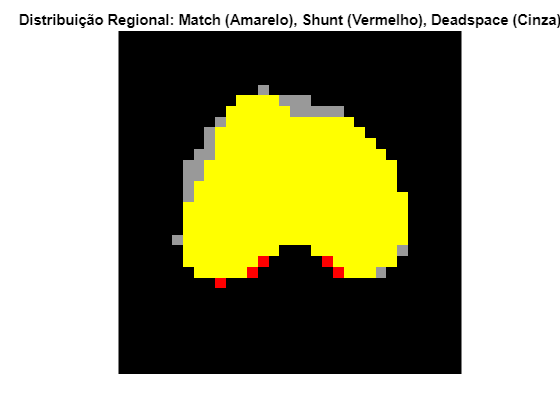


%% 8.1 Visualização do Mapa de Classificação V/Q
mapa_classificacao = zeros(linhas, colunas);
mapa_classificacao(R_VP) = 3; % Amarelo (Match)
mapa_classificacao(R_P)  = 2; % Vermelho (Shunt)
mapa_classificacao(R_V)  = 1; % Cinza/Azul (Deadspace)
mapa_classificacao(~mascara_pulmao) = 0; % Fundo (Preto)

% Definição do Colormap (Fundo=Preto, 1=Cinza, 2=Vermelho, 3=Amarelo)
cmap_vq = [0 0 0; 0.6 0.6 0.6; 1 0 0; 1 1 0]; 

figure('Name', 'Distribuição Categórica V/Q');
imagesc(mapa_classificacao);
colormap(gca, cmap_vq);
axis square off;
title('Distribuição Regional: Match (Amarelo), Shunt (Vermelho), Deadspace (Cinza)');

## 8. Estatísticas de Curva: Sinal Filtrado vs Dataset Referência

Busca-se utilizar a Raiz do Erro Quadrático Médio Normalizado (NRMSE) e o Coeficiente de Correlação de Pearson (r). NRMSE quantifica a discrepância entre as duas séries temporais de um mesmo piel, normalizado pela variabilidade do sinal de referência, tornando-a vantajosa para comparar sinais que apresentam diferentes amplitudes (busca-se valor próximo de 0). Já o Coeficiente de Correlação de Pearson avalia a relação linear entre as séries temporais, com o objetivo de avaliar a consistência no formato da onda independentemente da escala absoluta do sinal (busca-se coeficiente próximo de 1).

%% Validação 1D (Comparação Temporal entre Sinais Filtrados e Referência)

% As variáveis 'pletis_perf' (nosso sinal filtrado global) e 'pletis_ref_zero' 
% (sinal de referência pré-processado centralizado) já devem estar disponíveis no workspace, 
% conforme implementado em etapas anteriores do seu código.

% 1. Alinhamento de Tamanho (Garantia de segurança para as métricas)
% O NRMSE e a correlação de Pearson exigem vetores do mesmo tamanho.
tamanho_minimo = min(length(pletis_perf), length(pletis_ref_zero));
sinal_estimado = pletis_perf(1:tamanho_minimo);
sinal_referencia = pletis_ref_zero(1:tamanho_minimo);

% Para garantir que as métricas sejam calculadas no vetor em formato coluna 
sinal_estimado = sinal_estimado(:);
sinal_referencia = sinal_referencia(:);

%% 2. Cálculo do Normalized Root Mean Square Error (NRMSE)
% O NRMSE mede o erro quadrático normalizado pela variância da referência[cite: 127].
% Um NRMSE de 0 indica correspondência perfeita[cite: 127].
media_ref = mean(sinal_referencia);
numerador_nrmse = sqrt(sum((sinal_estimado - sinal_referencia).^2));
denominador_nrmse = sqrt(sum((sinal_referencia - media_ref).^2));

if denominador_nrmse == 0
    nrmse_valor = NaN; % Evita divisão por zero
else
    nrmse_valor = numerador_nrmse / denominador_nrmse;
end

%% 3. Cálculo da Correlação de Pearson (r)
% O r de Pearson mede a similaridade morfológica (relação linear)[cite: 127].
% Um valor próximo a 1 indica alta concordância no formato do sinal[cite: 127].
[r_pearson_matriz, ~] = corrcoef(sinal_referencia, sinal_estimado);
% O comando corrcoef retorna uma matriz 2x2. A correlação está fora da diagonal.
r_pearson = r_pearson_matriz(1, 2);

%% 4. Exibição dos Resultados no Terminal
fprintf('\n==== MÉTRICAS DE SIMILARIDADE 1D ====\n');


==== MÉTRICAS DE SIMILARIDADE 1D ====


fprintf('Comparação entre o pletismograma global filtrado e o pletismograma de referência.\n');

Comparação entre o pletismograma global filtrado e o pletismograma de referência.


fprintf('NRMSE:                 %5.4f\n', nrmse_valor);

NRMSE:                 5.3502


fprintf('Correlação de Pearson: %5.4f\n', r_pearson);

Correlação de Pearson: 0.7714


fprintf('--------------------------------------\n');

--------------------------------------


## 9. Sinais Separados: Perfusão e Ventilação

Com o sinal de respiração retirado e ao se obter uma curva que se assemelha à perfusão, é possível plotar o sinal original, o sinal de perfusão e o sinal de ventilação separados.

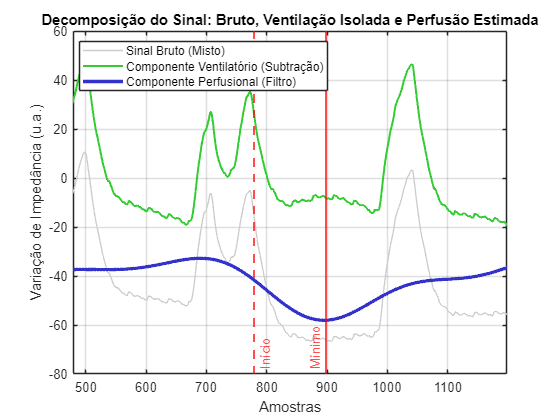

%% Visualização dos sinais Separados: Pletismograma vs Perfusão vs Ventilação

%pletis_ref_global = squeeze(sum(pletis_ref_3d, [1 2]));
%linha_base_ref = mean(pletis_ref_global(1:50));
%pletis_ref_zero = pletis_ref_global - linha_base_ref;

pletis_apenas_vent = pletis_global_zero - pletis_perf;
%pletis_apenas_vent = pletis_ventilacao_1d - pletis_perf;


% 2. Criação do Gráfico
%fig2b = figure('Visible', 'off', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.4]);
figure;
% Sinal Bruto (Ventilação + Salina) em Cinza Claro ao fundo
plot(pletis_global_zero, 'Color', [0.8 0.8 0.8], 'LineWidth', 1); hold on;

% Sinal Ventilatório Isolado (Subtração) em Verde
plot(pletis_apenas_vent, 'Color', [0.2 0.8 0.2], 'LineWidth', 1.5); 

% Sinal Perfusional Isolado (Filtro Butterworth) em Azul Escuro
plot(pletis_perf, 'Color', [0.2 0.2 0.8], 'LineWidth', 2.5); 

% Delimitadores de Tempo da Injeção
xline(idx_inicio, 'r--', 'Início', 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'right', 'LineWidth', 1.5);
xline(idx_fim, 'r-', 'Mínimo', 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'left', 'LineWidth', 1.5);

% Formatação do Gráfico
title('Decomposição do Sinal: Bruto, Ventilação Isolada e Perfusão Estimada'); 
xlabel('Amostras'); 
ylabel('Variação de Impedância (u.a.)');
legend('Sinal Bruto (Misto)', 'Componente Ventilatório (Subtração)', 'Componente Perfusional (Filtro)', 'Location', 'best');
grid on; 
xlim([max(1, idx_inicio - 300), min(length(pletis_perf), idx_fim + 300)]); % Zoom na injeção

## Funções Locais:

function [matriz_perf_3d, matriz_vent_3d, mask_ROI] = filt_Matriz3D(pletis_ventilacao_3d, Fs, f_p, f_v)
    [linhas, colunas, frames] = size(pletis_ventilacao_3d);
    matriz_perf_3d = zeros(linhas, colunas, frames);
    matriz_vent_3d = zeros(linhas, colunas, frames);
    
    % ROI Dinâmica baseada no TIV (Variação de Impedância Tidal)
    z_max = max(pletis_ventilacao_3d, [], 3);
    z_min = min(pletis_ventilacao_3d, [], 3);
    mapa_tiv = z_max - z_min;
    
    tiv_maximo = max(mapa_tiv(:));
    limiar_relativo = 0.10 * tiv_maximo;
    mask_ROI = mapa_tiv > limiar_relativo;
    
    for i = 1:linhas
        for j = 1:colunas
            if mask_ROI(i, j)
                pixel_sinal = squeeze(pletis_ventilacao_3d(i, j, :));
                
                % Ancora o sinal do pixel localmente no zero antes de filtrar
                linha_base_pixel = mean(pixel_sinal(1:50));
                pixel_sinal_zero = pixel_sinal - linha_base_pixel;
                
                matriz_perf_3d(i, j, :) = passa_baixa_sos(pixel_sinal_zero, f_p, Fs);
                matriz_vent_3d(i, j, :) = passa_baixa_sos(pixel_sinal_zero, f_v, Fs);
            end
        end
    end
end

function [sinal_filtrado, fc] = passa_baixa_sos(sinal_bruto, fc, Fs)
    Wn = fc / (Fs / 2);
    
    % 1. Projeto do filtro usando Zeros, Polos e Ganho (Evita instabilidade do [b,a])
    [z, p, k] = butter(9, Wn, 'low');
    
    % 2. Conversão para a Matriz de Seções de Segunda Ordem (SOS)
    [sos, g] = zp2sos(z, p, k);
    
    % 3. Filtragem zero-phase utilizando a estrutura SOS
    sinal_filtrado = filtfilt(sos, g, sinal_bruto);
end

function stats =  busca_maxEmin(dados)
    %% Busca pelos máx e mín
    N = size(dados,3);
    % --- 1. Encontrando a MAIOR amplitude ---
    % 'max_val' guarda o valor máximo e 'idx_max' guarda o índice linear
    [max_val, idx_max] = max(dados, [], 'all');
    
    % Convertendo o índice linear nas coordenadas 3D
    [linha_max, col_max, prof_max] = ind2sub(size(dados), idx_max);
    
    
    % --- 2. Encontrando a MENOR amplitude ---
    [min_val, idx_min] = min(dados, [], 'all');
    
    % Convertendo o índice linear nas coordenadas 3D
    [linha_min, col_min, prof_min] = ind2sub(size(dados), idx_min);
    
    % --- Exibindo os resultados no Command Window ---
    fprintf('Maior amplitude: Z = %f no pixel (%d, %d) no frame %d de %d\n', ...
        max_val, linha_max, col_max, prof_max, N);
    fprintf('Menor amplitude: Z = %f no pixel (%d, %d) no frame %d de %d\n', ...
        min_val, linha_min, col_min, prof_min, N);

    stats = [max_val,linha_max,col_max,prof_max, ...
            min_val,linha_min,col_min,prof_min];

end

function [pletis_global, pletis_ROI_out] = Samuel_visualizar_dados_Gao(pletis_ventilacao_3d, pletis_global_zero, pletis_perf, pletis_ROI_zero, pletis_ROI_perf, stats, intervalo, visualizar_minROI, idx_inicio, idx_fim)
    
    % Extração para a saída
    pletis_global = squeeze(sum(pletis_ventilacao_3d, [1 2])); 
    linha_max = stats(2);
    coluna_max = stats(3);
    pletis_ROI_out = squeeze(pletis_ventilacao_3d(linha_max, coluna_max, :));
    
    figure('Units', 'normalized', 'Position', [0.2 0.2 0.6 0.6], 'Name', 'Identificação da Janela de Perfusão (Método Gao)');
    
    %% Plot do Pletismograma Global
    subplot(2,1,1);
    % Plotamos o global centralizado, em cinza claro ao fundo (opcional para didática)
    plot(pletis_global_zero, 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
    hold on;
    % Plotamos o global filtrado
    plot(pletis_perf, 'Color', [0 0.4470 0.7410], 'LineWidth', 2);
    
    % Linhas Verticais
    xline(idx_inicio, 'r--', 'Início Queda', 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'right', 'LineWidth', 1.5);
    xline(idx_fim, 'r-', 'Pico Salina', 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'left', 'LineWidth', 1.5);
    
    title('Pletismograma Global (Filtro Passa-Baixa 0.17 Hz)');
    xlabel('Amostras');
    ylabel('Impedância (u.a.)');
    grid on;
    xlim([0 length(pletis_global_zero)]);
    
    %% Plot do Pletismograma do Pixel ROI (O que determinou o tempo)
    subplot(2,1,2);
    % Sinal do ROI não-filtrado em cinza claro ao fundo
    plot(pletis_ROI_zero, 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
    hold on;
    % Sinal do ROI FILTRADO (onde a busca matemática ocorreu)
    plot(pletis_ROI_perf, 'Color', [0 0.4470 0.7410], 'LineWidth', 2.5);
    
    % Linhas Verticais
    xline(idx_inicio, 'r--', 'Início Queda', 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'right', 'LineWidth', 1.5);
    xline(idx_fim, 'r-', 'Pico Salina', 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'left', 'LineWidth', 1.5);
    
    title(sprintf('Sinal de Impedância Local do Pixel ROI (%d, %d)', linha_max, coluna_max));
    xlabel('Amostras');
    ylabel('Impedância (u.a.)');
    grid on;
    xlim([0 length(pletis_ROI_zero)]);
end

function [P1,f] = FFT_Samuel(pletis_ROI) 

    % 1. Definição dos parâmetros exatos
    fs = 50;                 % Frequência de amostragem do EIT em Hz
    T = 1/fs;                % Período de amostragem (0.02 segundos)
    Nfft = 8192*4;


    % Interpolação:
    Upsampling=1; % upsampling não foi utilizado
    pletis_Interpolado = interp(pletis_ROI, Upsampling);

    % Nova taxa de amostragem
    fs_novo = fs * Upsampling;
    L = length(pletis_Interpolado);

    % aplicação de Zero-Padding (COMENTAR caso não for usar)
    % Se L for forçado a Nfft, o zero-padding aumenta a resolução de 
    % visualização (interpolação espectral), mas a resolução real de 
    % Rayleigh continua dependendo da janela de tempo do sinal.
    L = Nfft;
    
    % Vetor de tempo corrigido (opcional)
    T_novo = 1/fs_novo;
    t = (0:L-1)*T_novo;          % Vetor de tempo (opcional, para plot temporal)
    
    % 2. Aplicação da Transformada Rápida de Fourier
    Y = fft(pletis_Interpolado, L);
    
    % 3. Cálculo do espectro de magnitude
    % A FFT retorna valores complexos. Tiramos o módulo para ver a amplitude.
    P2 = abs(Y/L); % Espectro bilateral (two-sided) normalizado pelo tamanho L
    
    % 4. Conversão para espectro unilateral (single-sided)
    % Como o sinal é real, o espectro é simétrico. Pegamos apenas a metade positiva
    % e dobramos a amplitude (exceto da componente DC, que fica no índice 1).
    P1 = P2(1:floor(L/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    
    % 5. Definição do vetor de frequências em Hertz, com o NOVO fs
    f = fs_novo * (0:(floor(L/2)))/L;

    % Normalização do pico máximo
    P1 = P1/max(P1);
    
    % 6. Plotagem do Espectro
    figure;
    plot(f, P1, 'LineWidth', 1.5);
    title(sprintf('Espectro de Magnitude Unilateral de ROI1'));
    xlabel('Frequência (Hz)');
    ylabel('|P1(f)| (Amplitude normalizada)');
    grid on;
    
    % Focando nas baixas frequências
    xlim([0, 2.5]); % Exemplo: limitando a visualização de 0 a 2.5 Hz

end

function frame_nums = plot_frames_Samuel(img_frames_f, mask, idx_inicio, idx_fim)
    dim_frame = size(img_frames_f, 1);
    movien = 8;  % Gerar 8 frames (como no seu script original)
    
    % Definir os frames igualmente espaçados no intervalo do contraste
    moviet = round(linspace(idx_inicio, idx_fim, movien));
    
    % CORREÇÃO: Cálculo da DERIVADA TEMPORAL (taxa de variação)
    % A função gradient para matriz 3D retorna as derivadas em X, Y e Z (Tempo).
    % Usamos [~, ~, Z] para ignorar as derivadas espaciais e pegar apenas a temporal.
    % O sinal de negativo (-img_frames_f) inverte a queda (salina) para um pico positivo (brilho).
    [~, ~, img_frames_deriv] = gradient(-img_frames_f);
    
    img_diff = zeros(dim_frame, dim_frame, movien);
    
    for i = 1:movien
        % Extrai a derivada no instante exato do frame e aplica a máscara pulmonar
        img_diff(:,:,i) = img_frames_deriv(:,:,moviet(i)) .* mask;
        
        % Zera valores negativos (onde a impedância está subindo ou estagnada)
        img_diff(img_diff < 0) = 0; 
    end
    
    % Normalização global para os frames (0 a 1) para manter a escala consistente
    movierawmax = max(img_diff(:));
    if movierawmax == 0, movierawmax = 1; end % Proteção contra divisão por zero
    img_diff_norm = img_diff ./ movierawmax;

    % --- Definição do Colormap Personalizado de Perfusão ---
    colorperfraw1 = [0 0.4 0.6 1]';
    colorperfraw2 = 1/255 * [0 0 0; 200 29 0; 255 0 0; 255 241 89];
    colorperf0 = linspace(0, 1, 256)';
    colorperf = zeros(256, 3);
    for c = 1:3
        colorperf(:, c) = interp1(colorperfraw1, colorperfraw2(:, c), colorperf0);
    end

    % --- Plotagem da Linha do Tempo ---
    figure('Units', 'normalized', 'Position', [0.1 0.3 0.8 0.3], 'Name', 'Dinâmica do Fluxo de Salina (Derivada)');
    for i = 1:movien
        subplot(1, movien, i);
        imagesc(img_diff_norm(:, :, i), [0 1]);
        axis square off;
        title(['Frame ', num2str(moviet(i))]);
    end
    colormap(colorperf);
    
    frame_nums = moviet;
end